# Step 1: Detect a Face To Track

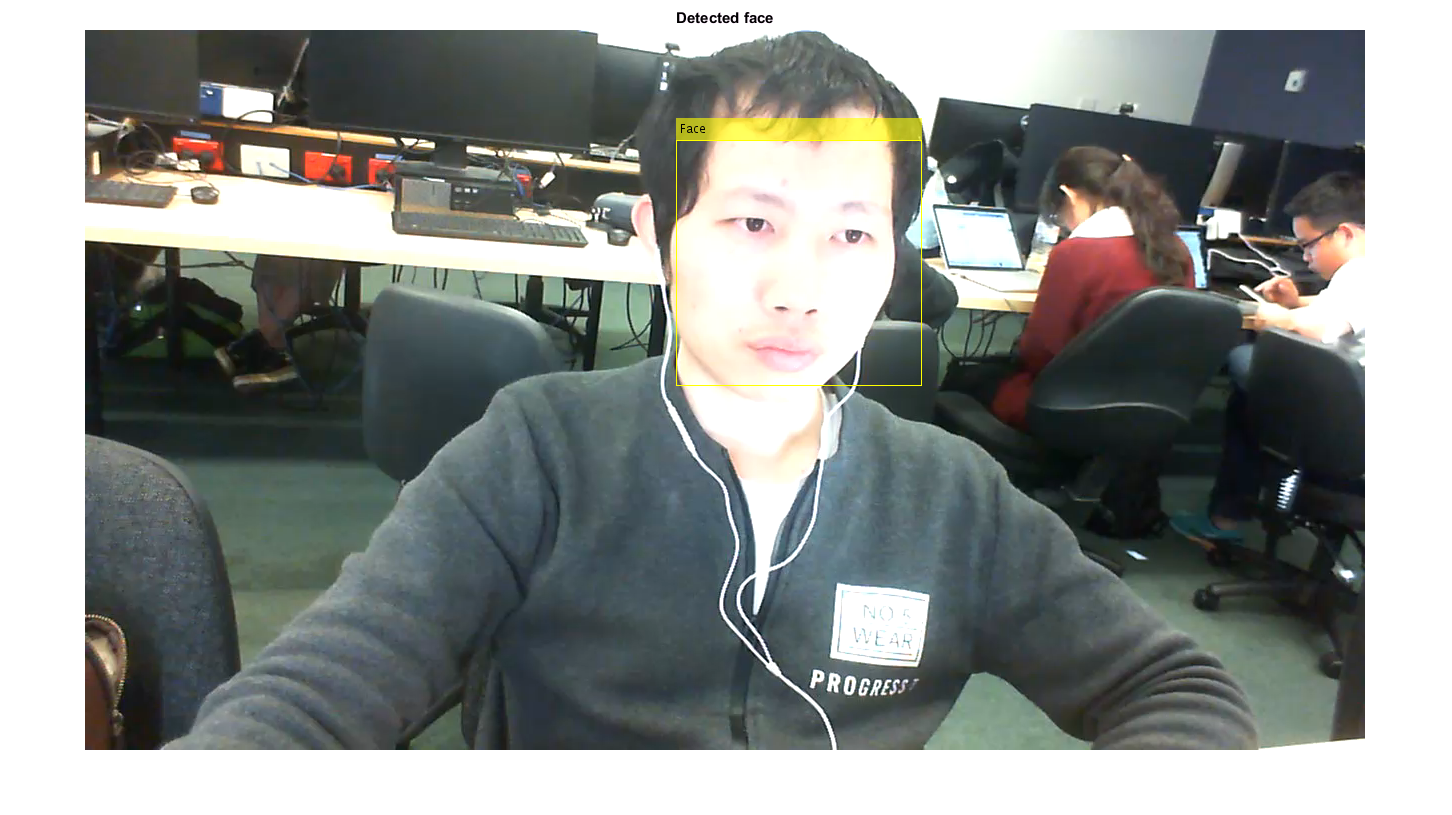

% Create a cascade detector object.
faceDetector = vision.CascadeObjectDetector();

% Read a video frame and run the detector.
videoFileReader = vision.VideoFileReader('1.MP4');
videoFrame      = step(videoFileReader);
bbox            = step(faceDetector, videoFrame);

% Draw the returned bounding box around the detected face.
videoOut = insertObjectAnnotation(videoFrame,'rectangle',bbox,'Face');
figure, imshow(videoOut), title('Detected face');

## Step 2: Identify Facial Features To Track

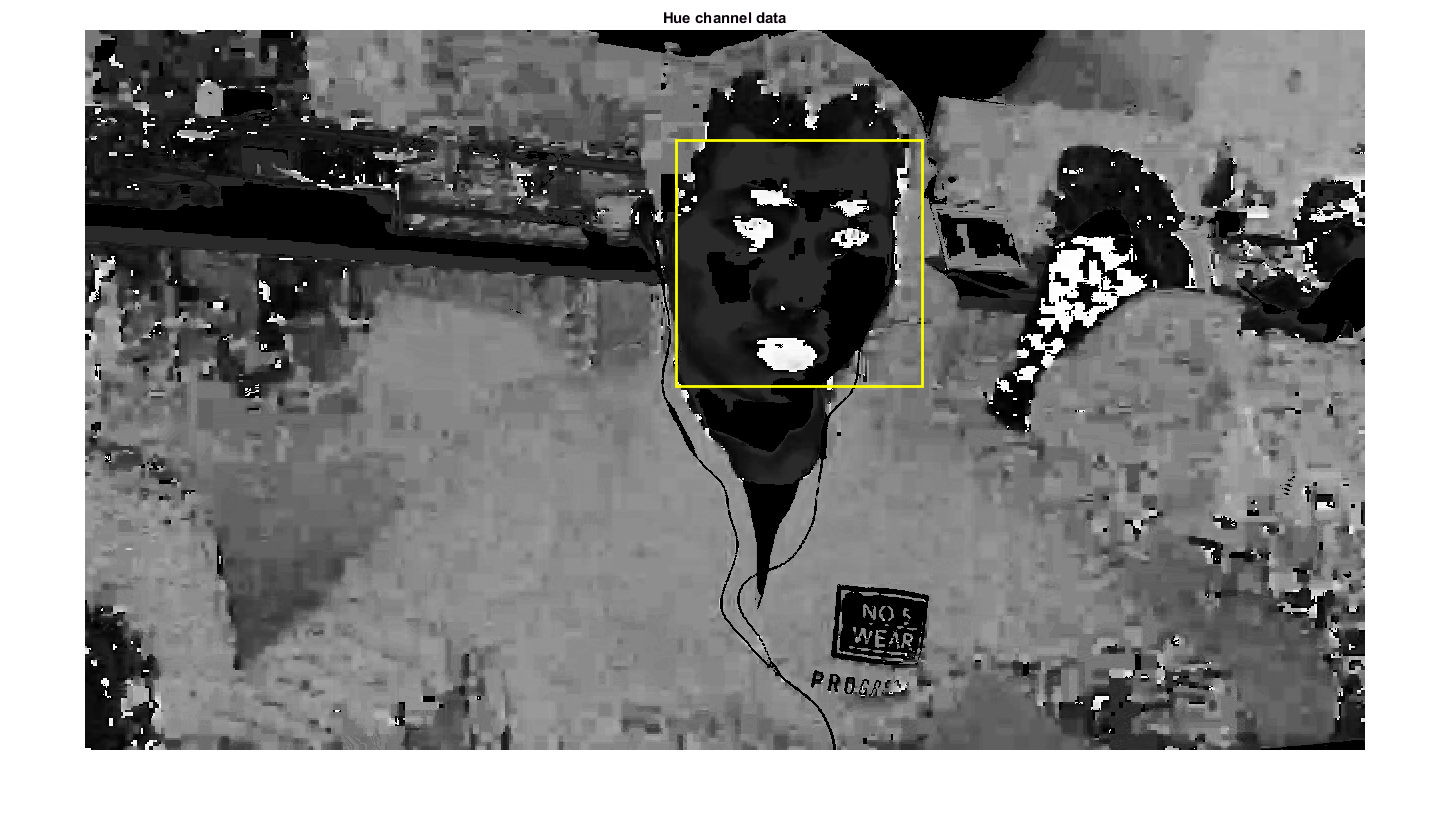

% Get the skin tone information by extracting the Hue from the video frame
% converted to the HSV color space.
[hueChannel,~,~] = rgb2hsv(videoFrame);

% Display the Hue Channel data and draw the bounding box around the face.
figure, imshow(hueChannel), title('Hue channel data');
rectangle('Position',bbox(1,:),'LineWidth',2,'EdgeColor',[1 1 0])

## Step 3: Track the Face

% Detect the nose within the face region. The nose provides a more accurate
% measure of the skin tone because it does not contain any background
% pixels.
noseDetector = vision.CascadeObjectDetector('Nose', 'UseROI', true);
noseBBox     = step(noseDetector, videoFrame, bbox(1,:));

% Create a tracker object.
tracker = vision.HistogramBasedTracker;

% Initialize the tracker histogram using the Hue channel pixels from the
% nose.
initializeObject(tracker, hueChannel, noseBBox(1,:));

% Create a video player object for displaying video frames.
videoInfo    = info(videoFileReader);
videoPlayer  = vision.VideoPlayer('Position',[300 300 videoInfo.VideoSize+30]);

% Track the face over successive video frames until the video is finished.
while ~isDone(videoFileReader)

    % Extract the next video frame
    videoFrame = step(videoFileReader);

    % RGB -> HSV
    [hueChannel,~,~] = rgb2hsv(videoFrame);

    % Track using the Hue channel data
    bbox = step(tracker, hueChannel);

    % Insert a bounding box around the object being tracked
    videoOut = insertObjectAnnotation(videoFrame,'rectangle',bbox,'Face');

    % Display the annotated video frame using the video player object
    step(videoPlayer, videoOut);

end

% Release resources
release(videoFileReader);
release(videoPlayer);

Error using rgb2hsv>parseInputs (line 95)
MAP must be a Mx3 array.

Error in rgb2hsv (line 36)
[r, g, b, isColorMap, isEmptyInput, isThreeChannel] = parseInputs(varargin{:});